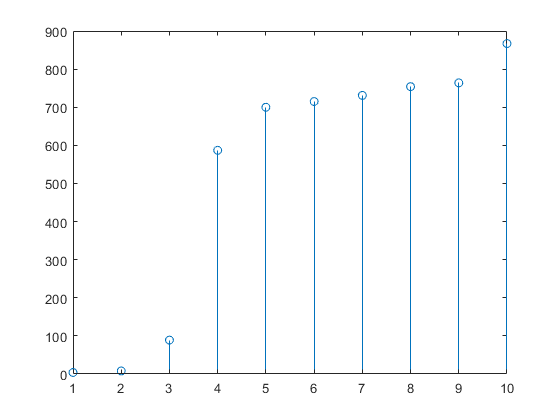

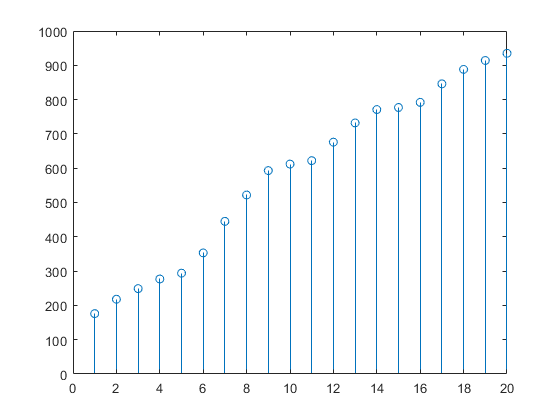

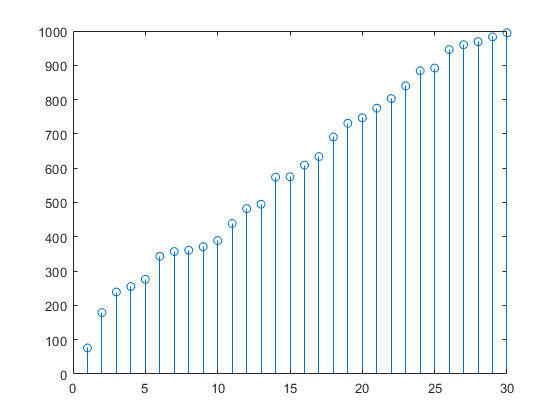

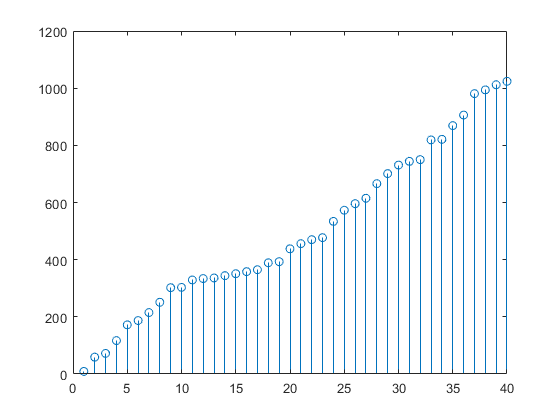

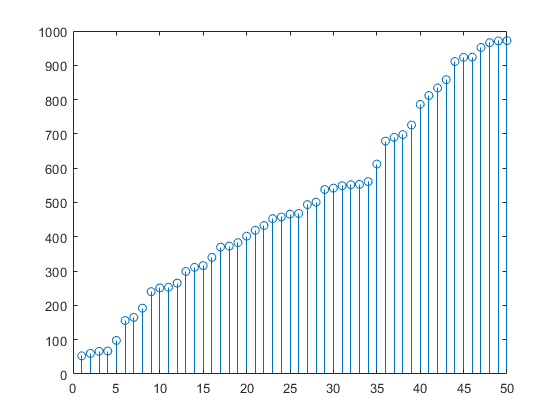

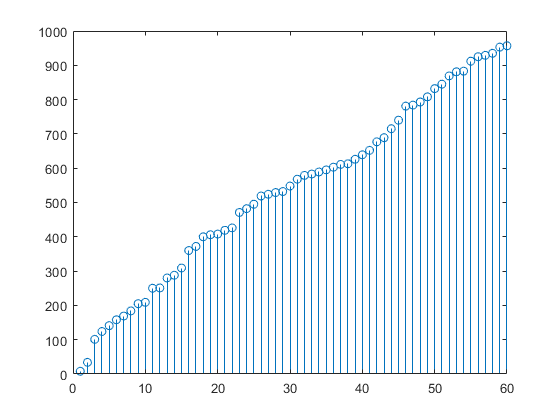

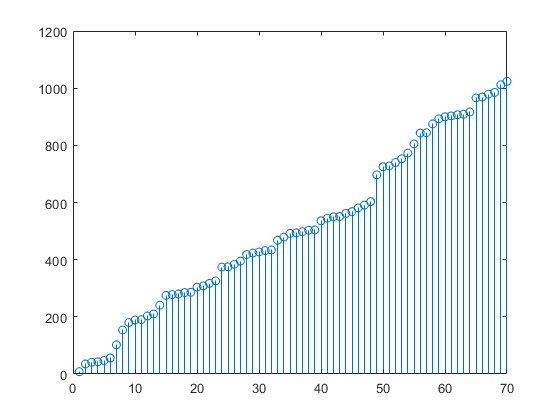

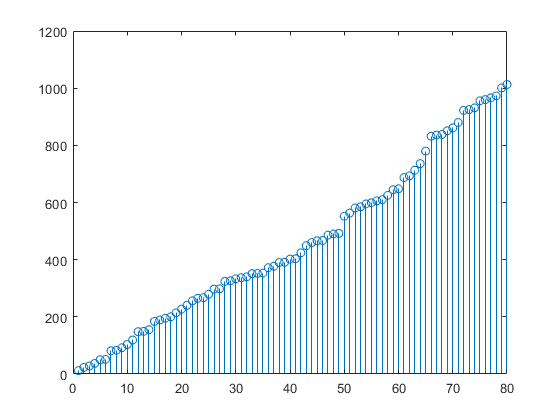

addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\lowerLevelCode\MISC");
clear;clc;
% Example usage
n = 1024;  % Total number of bits
x_array = [10:10:150];   % Number of ones
dataCols=[];
dataColsComp=[];
for x=x_array
    [random_array,random_array_comp,one_indices] = generate_random_array(n, x);
    figure();
    stem(one_indices);
    dataCols=[dataCols;[random_array,zeros(1,1092-1024)]];
    dataColsComp=[dataColsComp;[random_array_comp,zeros(1,1092-1024)]];
end

save("./dataCols.mat","dataCols","dataColsComp");
